# **fourth Optimal Control Project**

# **Designing an LQG Controller Based on Least Squares for a System with White Process and Measurement Noise.**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

## Parameters

clear all
close all
clc

g = 9.8; m = 0.65;
Ix = 7.5e-3; Iy = 7.5e-3; Iz = 1.3e-2;

## Continuous-time linearized system

A = [0 1 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 g 0 0 0;
     0 0 0 1 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 g 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 1 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 1;
     0 0 0 0 0 0 0 0 0 0 0 0];

B = [0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     0 0 0 0;
     1/m 0 0 0;
     0 0 0 0;
     0 1/Ix 0 0;
     0 0 0 0;
     0 0 1/Iy 0;
     0 0 0 0;
     0 0 0 1/Iz];

C = [1 0 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 1 0 0 0;
     0 0 0 0 0 0 0 0 0 0 1 0];

D = zeros(size(C,1), size(B,2));

## Discretize the system

Ts = 0.01;
sys = ss(A,B,C,D);
sysd = c2d(sys, Ts);
phi = sysd.A;
gamma = sysd.B;
Cd = sysd.C;


## Simulation setup

N = 5000;                       
x = zeros(12, N+1);           
x(:,1) = 0.2 * ones(12,1);    
u = zeros(4,N);                
z = zeros(6,N);                

Q = diag([1000 1 1000 1 1000 1 1 1 1 1 1 1]);
R = 0.01 * eye(4);
[Kd,~,~] = dlqr(phi, gamma, Q, R);

% Estimator initializations
xhat = zeros(12, N+1);         % Estimated state
P = 1e4 * eye(12);             % Initial covariance

% Noise
R_v = 1e-2 * eye(6);
v = mvnrnd(zeros(6,1), R_v, N)';  % Measurement noise

## Main loop

for k = 1:N
    
    x(:,k+1) = phi * x(:,k) + gamma * u(:,k);
    z(:,k+1) = Cd * x(:,k+1) + v(:,k);  

    x_pred = phi * xhat(:,k) + gamma * u(:,k);

    S = Cd * P * Cd' + eye(6);       
    K = P * Cd' / S;                 

    % Update step
    innovation = z(:,k+1) - Cd * x_pred;
    xhat(:,k+1) = x_pred + K * innovation;

    % Covariance update
    P = phi * (eye(12) - K * Cd) * P * phi';
    u(:,k+1) = -Kd*xhat(:,k+1);
end


time = 0:N-1;

## 1. Position: x, y, z

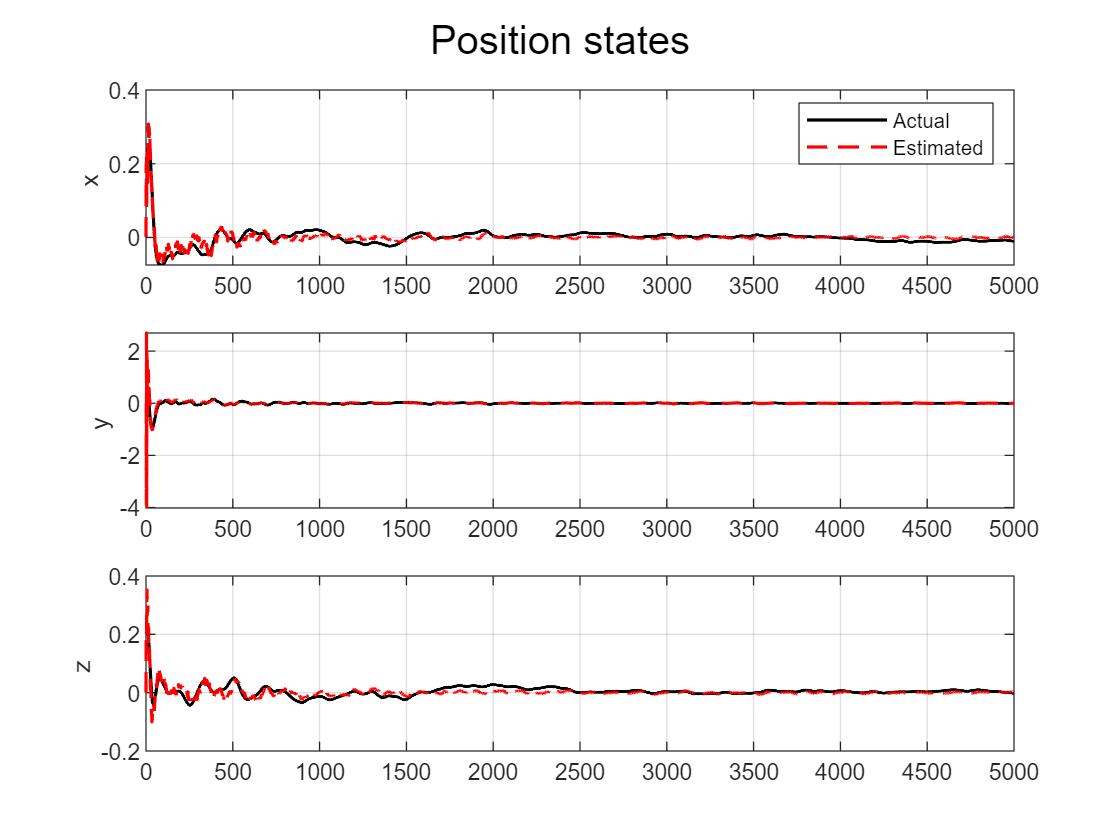

figure(1)
titles = {'x ', 'y ', 'z '};
for i = 1:3
    subplot(3,1,i)
    plot(time, x(i,1:N), 'k-', 'LineWidth', 1.2); hold on;
    plot(time, xhat(i,1:N), 'r--', 'LineWidth', 1.2);
    ylabel(titles{i});
    grid on;
    if i == 1
        legend('Actual', 'Estimated')
    end
end
sgtitle('Position states');

## 2. Velocities: x' y' z'

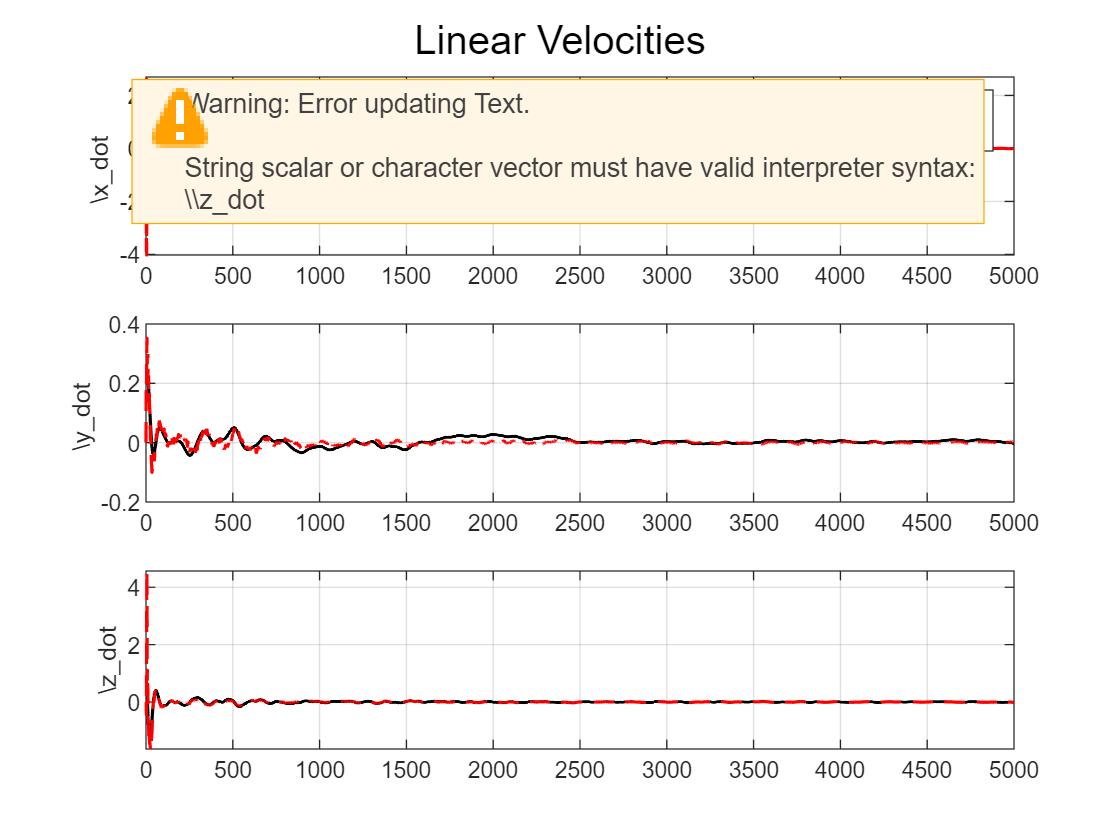

figure(2)
titles = {'\x_dot ', '\y_dot ', '\z_dot'};
for i = 1:3
    subplot(3,1,i)
    plot(time, x(i+1,1:N), 'k-', 'LineWidth', 1.2); hold on;
    plot(time, xhat(i+1,1:N), 'r--', 'LineWidth', 1.2);
    ylabel(titles{i});
    grid on;
    if i == 1
        legend('Actual', 'Estimated')
    end
end
sgtitle('Linear Velocities');

## 3. Angles: phi, theta, psi

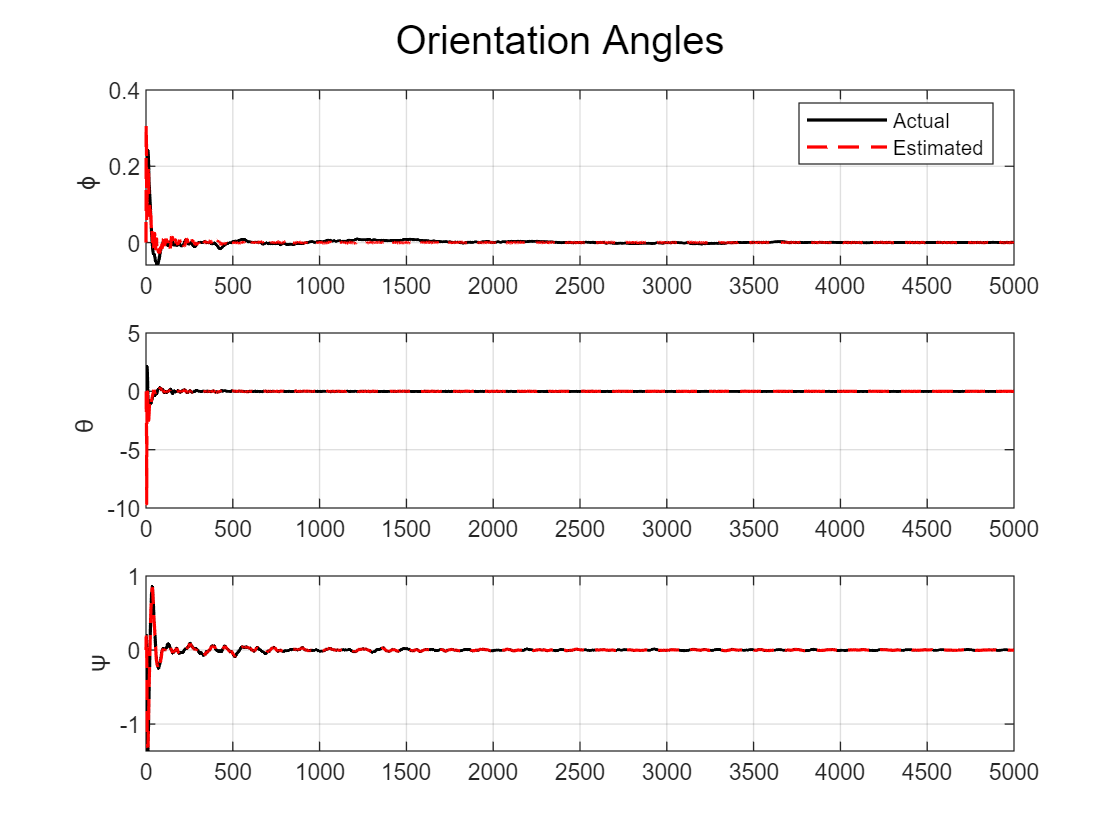

figure(3)
titles = {'\phi ', '\theta ', '\psi'};
for i = 1:3
    subplot(3,1,i)
    plot(time, x(i+4,1:N), 'k-', 'LineWidth', 1.2); hold on;
    plot(time, xhat(i+4,1:N), 'r--', 'LineWidth', 1.2);
    ylabel(titles{i});
    grid on;
    if i == 1
        legend('Actual', 'Estimated')
    end
end
sgtitle('Orientation Angles');

## 4. Angular Velocities: phi', theta', psi'

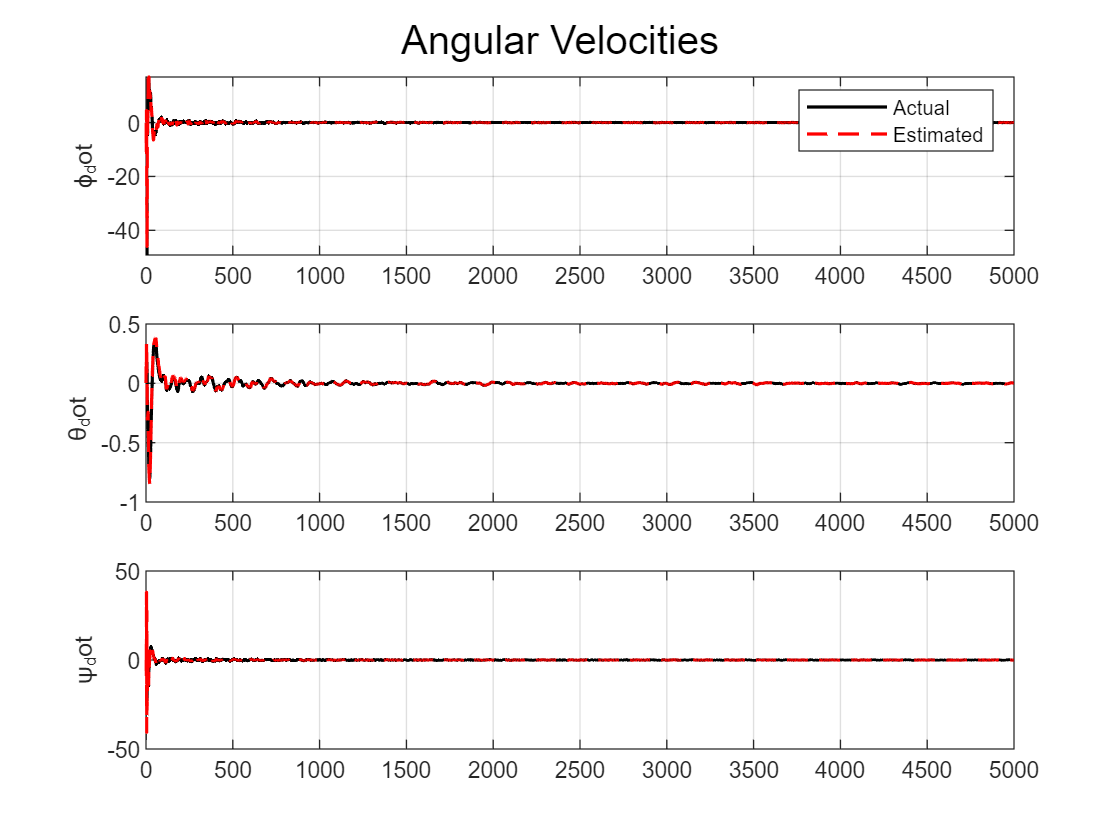

figure(4)
titles = {'\phi_dot', '\theta_dot ', '\psi_dot'};
for i = 1:3
    subplot(3,1,i)
    plot(time, x(i+7,1:N), 'k-', 'LineWidth', 1.2); hold on;
    plot(time, xhat(i+7,1:N), 'r--', 'LineWidth', 1.2);
    ylabel(titles{i});
    grid on;
    if i == 1
        legend('Actual', 'Estimated')
    end
end
sgtitle('Angular Velocities');

## 5. Control Inputs: u1, u2, u3, u4

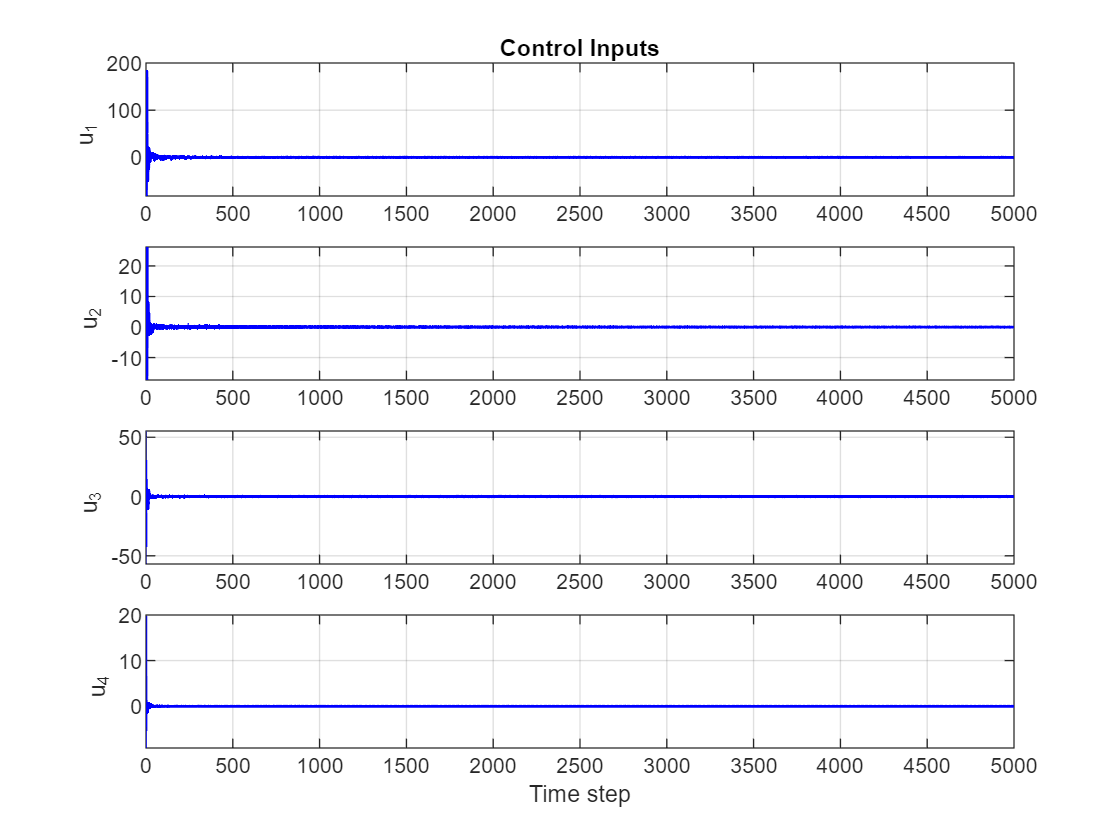

figure(5)
titles = {'u_1 ', 'u_2 ', 'u_3 ', 'u_4 '};
for i = 1:4
    subplot(4,1,i)
    plot(0:N-1, u(i,1:N), 'b-', 'LineWidth', 1.2);
    ylabel(titles{i});
    grid on;
    if i == 1
        title('Control Inputs')
    end
end
xlabel('Time step');